% PMU Linear State estimator
clear all
close all
clc
Vscale=440*sqrt(3);%kV
Iscale=1.500%kA

Iscale = 1.5000

Sbase=3000;%MVA
Vbase=Vscale;%kV
Ibase=Sbase/(sqrt(3)*Vbase) %kA

Ibase = 2.2727

Zbase=Vbase^2/Sbase

Zbase = 193.6000

econv=1e-7;
itermax=10;
R=3.18/Zbase; 
X=76.72/Zbase; 
Bsh=2*imag(inv(complex(0,-2040))*Zbase);
ldat0=zeros(1,13);
%		1	2	3	    4	    5	    6	    7   
ldat=	[	
        1	2	10001	R    	X	Bsh	10	 ;
        ];	
    ldat=horzcat(ldat,ldat0);
%  1  2      3	4	       5	     6          7          8        
bdat0=zeros(2,38-8);
bdat=	[	
   1  1001   1  0.0000000  0.0000000 0.0000000  0.0000000  1.0000   ;
   2  1002   3  0.0000000  0.0000000 0.8000000  0.6000000  1.0000  
   ];
 bdat=horzcat(bdat,bdat0);
zv=sqrt(3)*[209.083136564457;247.519574374358;384.442949792773;354.679052617344]/Vbase

zv =     0.4752
    0.5625
    0.8737
    0.8061


zi=[0.177608252957349;-0.533761114831566;0.617359756123962;-0.388369775206264]/Ibase

zi =     0.0781
   -0.2349
    0.2716
   -0.1709


z=[zv;zi];

% z=[V1mx; V2mx; V1my; V2my;I1mx; I2mx; I1my; I2my;];


% Options input: convergence;
tic;
%--------------------------------------------------------------------------------------------------
%Number of lines and Buses
nl=length(ldat(:,1));
n=length(bdat(:,1));
%
for i=1:n
   for j=1:n
Z(i,j)=10^20;
	end
end
for k=1:nl
   if ldat(k,1)>=ldat(k,2)
      Z(ldat(k,2),ldat(k,1))=complex(ldat(k,4),ldat(k,5));
      else
      Z(ldat(k,1),ldat(k,2))=complex(ldat(k,4),ldat(k,5));
end
end
for k=1:nl
   if ldat(k,1)>=ldat(k,2)
      su(ldat(k,2),ldat(k,1))=0.5*complex(0,ldat(k,6));
      else
      su(ldat(k,1),ldat(k,2))=0.5*complex(0,ldat(k,6));
   end
end
for i=1:n
   for j=1:n
      if i~=j
      su(j,i)=su(i,j);   
      end
   end
end
for i=1:n
   for j=1:n
      if i~=j
      Z(j,i)=Z(i,j);   
      end
   end
end

for k=1:nl
    if ldat(k,8)>0
      su(ldat(k,1),ldat(k,2))= inv(Z(ldat(k,1),ldat(k,2)))*((1-ldat(k,8))/ldat(k,8)^2);
      su(ldat(k,2),ldat(k,1))= inv(Z(ldat(k,2),ldat(k,1)))*((ldat(k,8)-1)/ldat(k,8));        
      Z(ldat(k,2),ldat(k,1))=ldat(k,8)*complex(ldat(k,4),ldat(k,5));
      Z(ldat(k,1),ldat(k,2))=Z(ldat(k,2),ldat(k,1));    
   end
end

for k=1:n    
sh(k,k)=complex(bdat(k,9),bdat(k,10));%include shunts at each bus% i=sqrt(-1);
end
%create Ybus
for i=1:n
   Y(i,i)=0;
   for j=1:n
      if i~=j
      Y(i,i)=inv(Z(i,j))+Y(i,i)+su(i,j);
      Y(i,j)=-inv(Z(i,j));   
      end
   end
end
Y=Y+sh;%Add (sh) shunt suceptance at buses

## PMU STATE ESTIMATOR

G=real(Y)

G =     0.1044   -0.1044
   -0.1044    0.1044


B=imag(Y)

B =    -2.4242    2.5191
    2.5191   -2.4242


Wv=ones(2*n,1)*(0.02*(Vscale/Vbase))^-2;
Wi=ones(2*n,1)*(0.01*(Iscale/Ibase))^-2;
W=diag([Wv;Wi]);
YY=[G,-B;B,G];
H=[eye(2*n,2*n);YY]

H =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000
    0.1044   -0.1044    2.4242   -2.5191
   -0.1044    0.1044   -2.5191    2.4242
   -2.4242    2.5191    0.1044   -0.1044
    2.5191   -2.4242   -0.1044    0.1044


x=inv(H'*W*H)*H'*W*z

x =     0.4764
    0.5631
    0.8723
    0.8053


h=H*x;
J=(z-h)'*W*(z-h)

J = 0.1338

m=length(z);
nve=length(x);
df=m-nve;
pValue=1-chi2cdf(J,df)%>.01% not suspicious bad data

pValue = 0.9979

Jcrit=chi2inv(.99,df)

Jcrit = 13.2767

J-Jcrit %<0 not suspicious bad data

ans = -13.1429

 % identyfying bad data 
uest=z-H*x;
Ks=H*inv(H'*W*H)*H'*W;
S=eye(m,m)-Ks;
Omega=S*inv(W);
r=S*uest;
rN=abs(r)./sqrt(diag(Omega));%if rN(j) > 3 j is bad data
max(rN);
[i]=find(rN==max(max((rN))))

i = 6

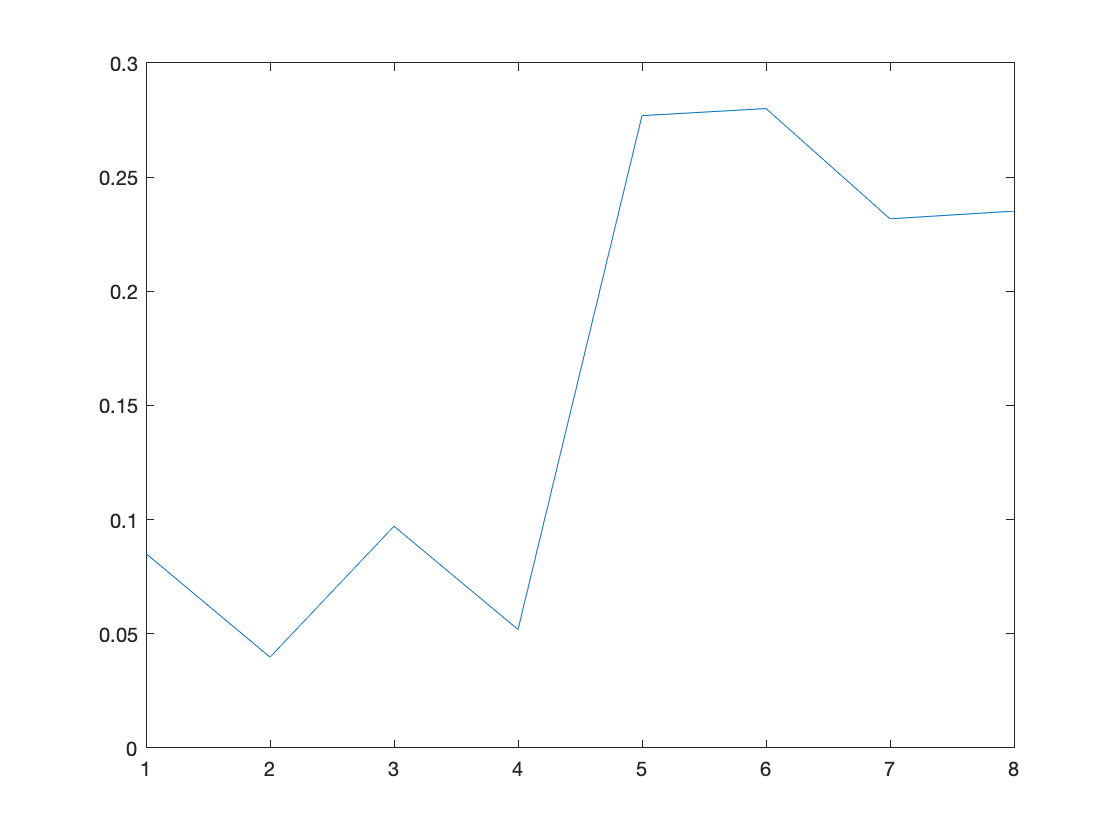

 figure
 plot(abs(z-h))
figure
plot(rN)

x*Vbase/sqrt(3) 

ans =   209.6317
  247.7759
  383.8171
  354.3447
